# Script to calculate the M1 AHU frequency response model

This script combines a state-space model representing the GMT's structural dynamics, the mount axes feedback controller transfer functions, optical sensitivity matrices, and rejection transfer functions to obtain the frequency responses between AHU force (and torque) inputs and segment tip-tilt and piston, and corresponding wavefront error at the exit pupil. The goal is to provide a transfer function matrix representing the telescope's sensitivity to forces applied into nodes at M1 air handling units locations.

The script to calculate the M1 AHU frequency responses relies on the following data files:

- **odc_fdr2023_z30_o**: It provides a struct object "o" with mount subsystem models, including the mount controller transfer functions.

- **lom_tt_dt** and **D_seg_piston_dt**: Those files provide linear approximations of the transformations from the M1 and M2 rigid-body motions to segment tip-tilt and piston at the telescope exit pupil.

- **modal_state_space_model_2ndOrder**: The file contains the telescope structural dynamics model represented in the second-order modal form. The variable *modelDescription* provides a detailed description of the model.

The first three files are available in the GitHub [repository](https://github.com/GMTO/m1_ahu_vibration). Here, we consider the model labeled as ***20251110_1617_zen_30_M1_202110_FSM_202305_Mount_202305_pier_202411_M1Fans***, saved in the GMTO-IM S3 bucket (s3://gmto.im.grim/). An alternative copy is available from the [SharePoint](https://gmtocorp-my.sharepoint.com/:f:/g/personal/rromano_gmto_org/EmzbZfW4IsdJgURWKF0hQ2IBpe8iteDaJeG9HE_u9bya-g?e=RxhsYi).

After running the script, the state-space model matrices are saved as ***G_20251110_1617zeta<.>pct_ahu_ss.mat***, and the output data ***G_20251110_1617zeta<.>pct_ahu_fr_var_<.>.mat*** file provides the frequency response model for each observing mode: `H_NS_ttp`, `H_NGAO_ttp`, and `H_LTAO_ttp`.

## Preamble

% Clear the workspace if this is not a nested run
runstack = dbstack;
if(numel(runstack) <= 1)
    clearvars;
    nested_run = false;
    plot_wfc_rtf = true;
else
    nested_run = true;
    if(~exist('plot_wfc_rtf','var')), plot_wfc_rtf = false; end
end

- Set telescope structural dynamics damping

sysDamp = 0.02;

- Structural model folder

femFolder = '/home/rromano/mnt';
modelLabel = '20251110_1617_zen_30_M1_202110_FSM_202305_Mount_202305_pier_202411_M1Fans';
ModelFolder = fullfile(femFolder, modelLabel);

## Load Integrated Model Subsystems

calc_fr = true;

% frequency response data file pattern
file_pattern = replace(sprintf('G_%szeta%gpct_ahu_fr',modelLabel(1:13),sysDamp*100),'.','p');
existing_files = dir([file_pattern,'*']);

if(nested_run && ~isempty(existing_files))
    fprintf("Checking for available FR files for model %s...\n", modelLabel(1:13));
    for i = 1:length(existing_files)
        % Get the full filename
        fr_filename = existing_files(i).name;

        load(fr_filename, 'G_fr','inputTable');
        mnt_TF_Ts = G_fr.Ts;
        om = G_fr.frequency;
        [ny, nu, ~] = size(G_fr);
        nw = length(om);

        if(isequal(2*pi*freq,G_fr.frequency))
            fprintf('FR data in %s matches the PSD frequency points for model\n%s\n',modelLabel);
            calc_fr = false;
            continue;
        end
    end
end


FileName = fullfile(ModelFolder,"modal_state_space_model_2ndOrder.mat");
if(~exist('inputTable','var') || calc_fr || false)
    
    fprintf("Loading modal model parameters from \n%s\n",FileName);
    load(FileName,'inputs2ModalF','modalDisp2Outputs',...
        'eigenfrequencies','inputTable','outputTable'); %'modelDescription'
    % Handle modal paramete
    om0 = eigenfrequencies(:)*2*pi;
    proportionalDampingVec = sysDamp*ones(size(eigenfrequencies(:)));
    twice_zom = 2*proportionalDampingVec.*om0;
    
    % State-space model matrices
    B = [zeros(size(inputs2ModalF)); inputs2ModalF];
    C = [modalDisp2Outputs, zeros(size(modalDisp2Outputs))];
    
    nm = size(inputs2ModalF,1);
    A = sparse([zeros(nm),eye(nm);-diag(om0.^2), -diag(twice_zom)]);
    
    fprintf("The model maximum eigenfrequency is %.5fHz\n",om0(end)/2/pi);
    
%     % Static solution gain matrix
%     staticSolFile = fullfile(ModelFolder,"static_reduction_model.mat");
%     try
%         load(staticSolFile,'gainMatrixMountControlled');
%         gainMatrix = gainMatrixMountControlled;
%     catch
%         load(staticSolFile,'gainMatrix');
%     end
% 
%     fprintf('Static gain matrix loaded from\n%s\n', staticSolFile);
end

Loading modal model parameters from 
/home/rromano/mnt/20251110_1617_zen_30_M1_202110_FSM_202305_Mount_202305_pier_202411_M1Fans/modal_state_space_model_2ndOrder.mat


The model maximum eigenfrequency is 299.89069Hz


### Load optical sensitivity matrices

The optical sensitivity matrices provide a linear approximation of the effect of telescope motion on the image at the exit pupil. There are two linear transformations: $L_\text{TT} \in \mathbb{R}^{14 \times 84}$ and $L_\text{P} \in \mathbb{R}^{7 \times 84}
$, which map the M1 and M2 rigid-body motions vector of the seven segments into segment tip-tilt (TT), and piston at the exit pupil, respectively.

As the telescope structural dynamics model has the M1 & M2 translations and rotations as outputs, the matrix 


$$L_o = \left[ L_\text{TT}^T \ L_\text{P}^T \right]^T$$


is a proxy to assess the effect of external forces (disturbances) on the image quality. The segment TT and piston are further mapped into the wavefront error, as described later.

filename1 = 'lom_tt_dt.mat';
load(filename1,'D_seg_tt');
fprintf('\nTT sensitivity matrix loaded from \n%s',filename1);


TT sensitivity matrix loaded from 
lom_tt_dt.mat

filename2 = 'D_seg_piston_dt.mat';
load(filename2,'D_seg_piston');
fprintf('\nPiston sensitivity matrix loaded from \n%s\n',filename2);


Piston sensitivity matrix loaded from 
D_seg_piston_dt.mat


### Extract subsystem with relevant inputs and outputs

The telescope structural dynamics model is a crucial element in analyzing the effect of external forces on the GMT's optical degrees of freedom. A subset of the complete structural dynamics model inputs and outputs is sufficient to profile the telescope's sensitivity to vibration sources.

**Subsystem with segment PTT outputs**

Such a subset has the M1&M2 rigid-body motions as outputs and the AHU node input loads (forces and moments). The telescope model subsystem transfer function $G(j\omega)$ also includes the mount drive torques and the mount axes motions so that the mount positioning feedback control system is incorporated into the results. We embed the optical sensitivity matrices into the obtained model.

if(calc_fr)
    % Pier force
    ahu_in = inputTable{'OSS_M1_fans_lcl_6F',"indices"}{1};
    % MNT drives input indices
    mntAZ_in = inputTable{'OSS_AzDrive_Torque',"indices"}{1};
    mntEL_in = inputTable{'OSS_ElDrive_Torque',"indices"}{1};
    mntGIR_in = inputTable{'OSS_RotDrive_Torque',"indices"}{1};

    % SS model input matrix
    b = [B(:,ahu_in),...
        mean(B(:,mntAZ_in),2), mean(B(:,mntEL_in),2), mean(B(:,mntGIR_in),2)];
    nu = size(b,2);

    % M1/M2 RBM
    m1_out = outputTable{'OSS_M1_lcl','indices'}{1};
    m2_out = outputTable{'MC_M2_lcl_6D','indices'}{1};
    % MNT enc output indices
    mntAZ_out = outputTable{'OSS_AzEncoder_Angle',"indices"}{1};
    mntEL_out = outputTable{'OSS_ElEncoder_Angle',"indices"}{1};
    mntGIR_out = outputTable{'OSS_RotEncoder_Angle',"indices"}{1};

    % SS model output matrix
    c = [[D_seg_tt; D_seg_piston]*[C(m1_out,:); C(m2_out,:)];...
        mean(C(mntAZ_out,:),1); mean(C(mntEL_out,:),1); mean(C(mntGIR_out,:),1)];
    ny = size(c,1);

    % Structure with model parameters
    obj_sys = struct('B',b, 'C',c, 'D',zeros(ny,nu));

    % Check to save sate-space model matrices
    if(false&& ~nested_run)
        C_ttp = c(1:end-3,:);
        B_ahu = b(:,1:end-3);
        ss_fname = replace(sprintf('G_%szeta%gpct_ahu_ss',modelLabel(1:13),sysDamp*100),'.','p');
        save(ss_fname,'A','B_ahu','C_ttp')
        fprintf("State-space structural model matrices saved in %s\n", ss_fname);
    end
end

### Load ODC mount drivers & controller model paremeters

Three transfer functions with a PID controller and notch filter terms (structural modes attenuation) compose the optical structure (mount) feedback control model $C_\text{mnt}(j\omega)$. The obtained control system (illustrated in the figure below) matches the performance and robustness requirements described in GMT-REQ-03215 and GMT-DOC-02011.

% Load ODC mount controller and driver parameters
try
    load("odc_fdr2023_z30_o",'o');
catch
    error("Unable to load ODC data!");
end

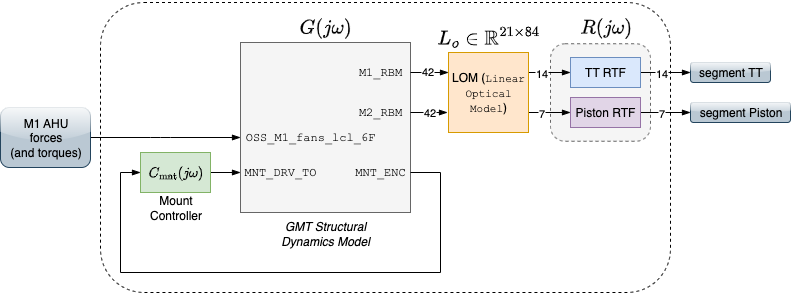

The block $R(j\omega)$ is the optical rejection transfer function used to represent the effect of the wavefront control system. One can perform the analysis considering the Natural Seeing (NS), the NGAO, or the LTAO (default) wavefront control modes.

## Frequency responses (FRs)

The procedure to obtain the transfer function from air handling unit forces to the wavefront error at the exit pupil has three steps. Let $n_y=21+3$, $n_u=((6 \cdot 14 \cdot 7)+3)$, and $n_\omega$ denote the dimesions of output, input and frequency points. First, we compute a $n_y \times n_u \times n_\omega$-dimensional frequency responses (FR) object representing the effect of forces (and torques) applied to the AHU nodes in the segment piston and tip-tilt (see the block diagram above).  To incorporate the mount controller effect, the FR object includes the mount drive torque inputs and the encoder outputs. Third, as described in the Section entitled Wavefront error response, the FR to white noise are combined, yielding to the wavefront at the exit pupil.

**Structural plant frequency response model**

if(~nested_run)
    % Specify the frequency points for a particular analysis
    nw = 2^9+1;
    FMAX = om0(end)/2/pi;
    freq = logspace(log10(0.05),log10(FMAX),nw);
end    

if(calc_fr)
    fprintf('Calculating FR model at the AHU PSD frequency points.\n');
    om = freq*2*pi;
    nw = length(om);

    fprintf("Computing frequency response from %.3g-%.3gHz\n",freq(1),freq(end));
    for ik = 1:7
        proper_ss_fr = bode_second_order(obj_sys,...
            om, om0, proportionalDampingVec, (1:6*14)+(ik-1)*6*14, 1:ny);
        eval(sprintf("s%d_fr = proper_ss_fr;",ik));
        fprintf("S%i done!\n",ik);
    end
    mnt_ss_fr = bode_second_order(obj_sys,om, om0, proportionalDampingVec, nu-2:nu, 1:ny);
    fprintf("AHU FR computation complete!\n")
    ss_fr = [s1_fr, s2_fr, s3_fr, s4_fr, s5_fr, s6_fr, s7_fr, mnt_ss_fr];
    G_fr = frd(ss_fr, om);

    % Find the highest X value in existing "var_X" files
    max_num = 0;
    for i = 1:length(existing_files)
        % Extract number from filenames like "filename_var_5.mat"
        tokens = regexp(existing_files(i).name, 'var_(\d+)', 'tokens');
        if ~isempty(tokens)
            num = str2double(tokens{1}{1});
            if num > max_num
                max_num = num;
            end
        end
    end
    % Create new filename with incremented number
    new_filename = sprintf('%s_var_%d.mat', file_pattern, max_num + 1);
    % Save FR data
    save([new_filename,'.mat'],"G_fr","ModelFolder","o","om","sysDamp","inputTable","-mat");
    fprintf("TF frequency response data saved as %s\n", new_filename);
    fr_filename = new_filename;
end

Calculating FR model at the AHU PSD frequency points.


Computing frequency response from 0.05-300Hz


S1 done!
S2 done!
S3 done!
S4 done!
S5 done!
S6 done!
S7 done!


AHU FR computation complete!

TF frequency response data saved as G_20251110_1617zeta2pct_ahu_fr_var_1.mat


**Mount Controller + drives FR models**

% Mount driver model parameters
mount.delay = 4.0e-3;     % [s] DRV delay: 4ms (GMT25-ANA-40000-0007-2.0 - Pg26)
if(~nested_run), fprintf('Driver delay set to %g ms.\n',mount.delay); end

Driver delay set to 0.004 ms.


% Current loop dynamics tranfer function
Hdrive_d = o.Hdrive(1,1);

% Azimuth
az_C_fr = frd(balreal(ss(o.az.c.Hp)), om);
az_delay_fr = frd(tf(1,1,'IOdelay', mount.delay), om);
az_drive_fr = frd(Hdrive_d, om);

% Elevation
el_C_fr = frd(balreal(ss(o.el.c.Hp)), om);
el_delay_fr = frd(tf(1,1,'IOdelay', mount.delay), om);
el_drive_fr = frd(Hdrive_d, om);

% GIR
gir_C_fr = frd(balreal(ss(o.gir.c.Hp)), om);
gir_delay_fr = frd(tf(1,1,'IOdelay', mount.delay), om);
gir_drive_fr = frd(Hdrive_d, om);

**Compute telescope FRF matrix considering the mount feedback control**

if(exist("C_fresp","var")), clear C_fresp; end
C_fresp(1:nu-3,1:nu-3) = eye(nu-3)*frd(tf(1,1),om);
C_fresp(nu-3+1,nu-3+1) = az_drive_fr * az_delay_fr * az_C_fr;
C_fresp(nu-3+2,nu-3+2) = el_drive_fr * el_delay_fr * el_C_fr;
C_fresp(nu,nu) = gir_drive_fr * gir_delay_fr * gir_C_fr;

H_mntFB = feedback(G_fr*C_fresp, eye(3), (1:3)+(nu-3), (1:3)+(ny-3));


### Verification transfer functions

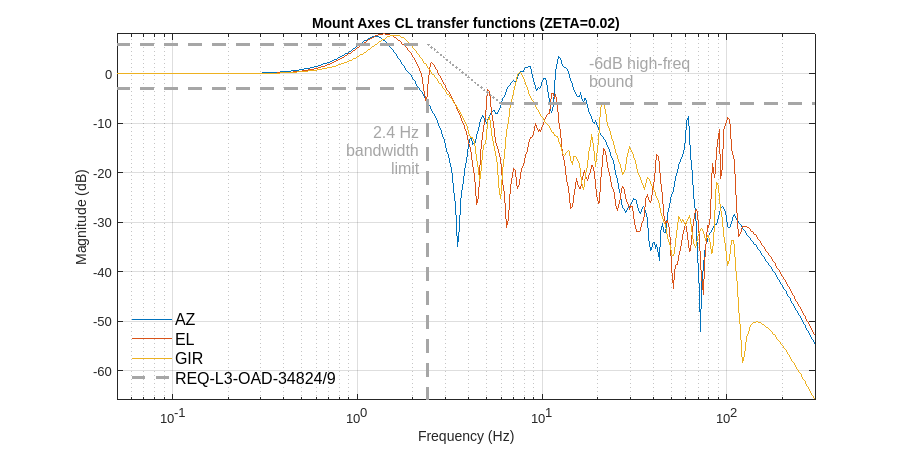

if(true&& ~nested_run) % Mount transfer function plot (optional)
    figure;
    set(gcf,'Position',[833   323   900   450])

    for i2 = 1:3
        hb = semilogx(om/2/pi, 20*log10(abs(squeeze(H_mntFB.ResponseData(ny-3+i2,nu-3+i2,:)))));
        hold on;
    end
    axis tight;
    plot_cl_OAD_req(2.4, 6);
    legend({'AZ','EL','GIR','REQ-L3-OAD-34824/9'},...
        'Fontsize',12,'location','southwest'); legend boxoff;
    
    title(sprintf('Mount Axes CL transfer functions (ZETA=%g)',sysDamp));
    ylabel('Magnitude (dB)');
    xlabel('Frequency (Hz)');
    grid on; hold off;    
end

**Compute NS, NGAO or LTAO RTFs **

The variable `rtf` is a $21\times21$matrix transfer function. The NS, NGAO, or LTAO (depending on the argument state of `WFC_MODE`) tip-tilt rejection transfer function (RTF) fills the first 14 main diagonal entries. The differential piston RTF fills the last 7 diagonal elements. The rejection transfer function matrix aims at reproducing the effect of the wavefront control loops.

% NS
rtfNS(1:14,1:14) = eye(14)*frd(oad_NS_rtf(om), om);
rtfNS(15:21,15:21) = eye(7)*frd(tf(1,1), om);
H_NS_ttp = rtfNS * H_mntFB(1:21,1:nu-3,:);
% NGAO
rtfNGAO(1:14,1:14) = eye(14)*frd(oad_NGAO_rtf(om), om);
rtfNGAO(15:21,15:21) = eye(7)*frd(oad_NGAO_rtf(om), om);
H_NGAO_ttp = rtfNGAO * H_mntFB(1:21,1:nu-3,:);
% LTAO
rtfLTAO(1:14,1:14) = eye(14)*frd(oad_LTAO_rtf(om), om);
rtfLTAO(15:21,15:21) = eye(7)*frd(oad_LTAOdp_rtf(om), om);
H_LTAO_ttp = rtfLTAO * H_mntFB(1:21,1:nu-3,:);

if(~nested_run)
    save([fr_filename,'.mat'],"H_NS_ttp","H_NGAO_ttp","H_LTAO_ttp","-mat",'-append');
end

if(~exist('WFC_MODE','var') && ~nested_run)
    WFC_MODE = "LTAO"
end

WFC_MODE = "LTAO"

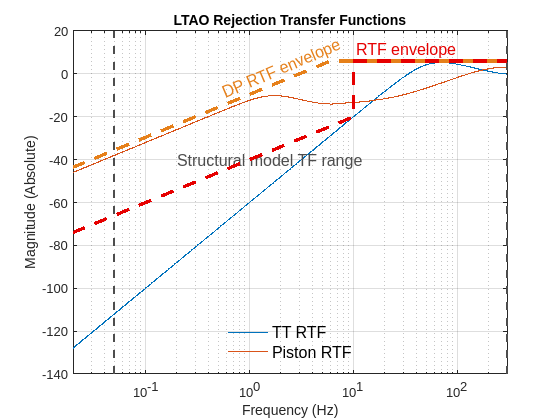


switch WFC_MODE
    case "NS"
        rtf = rtfNS; 
    case "NGAO"
        rtf = rtfNGAO;
    case "LTAO"
        rtf = rtfLTAO;
end
rtf = frd(rtf.ResponseData, om);

if(true)
    om__ = logspace(log10(0.02), log10(300), 1001)*2*pi;
    switch WFC_MODE
        case "NS"
        rtf1 = 20*log10(abs(oad_NS_rtf(om__)));
        rtf2 = zeros(size(om__));
        f_20dbref = 1;
    case "NGAO"
        rtf1 = 20*log10(abs(oad_NGAO_rtf(om__)));
        rtf2 = 20*log10(abs(oad_NGAO_rtf(om__)));
        f_20dbref = 10;
    case "LTAO"
        rtf1 = 20*log10(abs(oad_LTAO_rtf(om__)));
        rtf2 = 20*log10(abs(oad_LTAOdp_rtf(om__)));
        f_20dbref = 10;
    end
    figure;
    
    hp(1) = semilogx(om__/2/pi, rtf1); hold on;
    hp(2) = semilogx(om__/2/pi, rtf2);    
    text(4*om(1)/2/pi,-40,'Structural model TF range',...
        'Fontsize',12,'color',[.3 .3 .3]);
    yy = ylim;    
    plot([min(om)/2/pi,min(om)/2/pi],yy,'--','color',[.3 .3 .3],'Linewidth',1.5);
    plot([max(om)/2/pi,max(om)/2/pi],yy,'--','color',[.3 .3 .3],'Linewidth',1.5);
    if(WFC_MODE == "LTAO"), plot_Sdp_envelope(6); end
    plot_S_envelope(f_20dbref);
    title(sprintf('%s Rejection Transfer Functions',WFC_MODE));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (Absolute)');
    grid on; hold off;
    xlim([min(om__),max(om__)]/2/pi);
    legend(hp,{'TT RTF','Piston RTF'},'Fontsize',12,'Location','south');
    legend box off;    
end

% No WFC RTF
H_ttp = rtf*H_mntFB(1:21,1:nu-3,:); %#ok<*UNRCH> 

% Halt here for now.
if(nested_run)
    return;
end

### Segment Tip-tilt

Let $Y_\text{tt}(j\omega)$the 14-dimensional vector of segment tip-tilt after incorporating the effect of the rejection transfer function $$R(j\omega)$$. In the following, we present the segment tip-tilt magnitude frequency response $\breve{Y}_{\text{tt},i}(j\omega)$ for each segment $i \in \{1,2,\ldots,7\}$. The tip and tilt effects are combined in quadrature, i.e.,


$$\breve{Y}_{\text{tt},i}(j\omega) = 
\sqrt{
 \left(
Y_{\text{tt},i}(j\omega) \right) ^2 
+ \left(Y_{\text{tt},i+7}(j\omega)
\right)^2 }$$


where $Y_{\text{tt},i}(j\omega)$ denotes the $i^\text{th}$-element of $Y_\text{tt}(j\omega)$.

### Segment Piston

Next, we present each segment's relative piston error induced by the pier vibrations. The ***relative*** piston error $\breve{Y}_\text{piston}(j\omega)$means that the average over the seven segments is subtracted. So,


$$\breve{Y}_{\text{piston},i}(j\omega) = 
Y_{\text{piston},i}(j\omega) - \frac{1}{7} \sum_{i=1}^7
Y_{\text{piston},i}(j\omega) ,$$


where $Y_{\text{piston},i}(j\omega)$ denotes the $i^\text{th}$-element of the 7-dimensional vector $Y_\text{piston}(j\omega)$.

As previously for the segment TT, each plot shows the response for one element of the rigid-body force/moment vector.

### Wavefront error (WFE) response to white-noise

One can approximate the wavefront error***** induced by a white-noise as


$$Y_\text{wf}(j\omega) =
\sqrt{ \frac{1}{7}
 \sum_{i=1}^7
 \left(\rho \breve{Y}_{\text{tt},i}(j\omega)\right) ^2 
 +
\left(\breve{Y}_{\text{piston},i}(j\omega)\right)^2
},$$


where $\rho = 10.2 \text{nm}/\text{mas}$ is a scaling factor. Below, we present the white-noise response $\left|Y_\text{wf}(j\omega)\right|$. That can be seen as the transfer function from the forces (and moments) applied in the M1 AHU nodes to the wavefront error.

rad2mas = (180/pi * 3600 * 1000);

tt_frf = zeros(7, nu-3, nw);
piston_frf = zeros(size(tt_frf));
wfe_fr = zeros(nu-3, length(om));

for i2 = 1:nu-3
    tt_frf(:,i2,:) = 10.2* abs(rad2mas *sqrt(...
        H_ttp.ResponseData((1:7),i2,:).^2 + ...
        H_ttp.ResponseData((8:14),i2,:).^2));
    piston_frf(:,i2,:) = 1e9*abs(...
        H_ttp.ResponseData(15:21,i2,:)...
        - 1.0*mean(H_ttp.ResponseData(15:21,i2,:))...
        );
    % WFE from PTT optical sensitivity transformation matrices
    wfe_fr(i2,:) = sqrt(1/7) * sqrt(...
        sum(tt_frf(:,i2,:).^2) + sum(piston_frf(:,i2,:).^2));
end

**Save M1 AHU frequnecy response model**

if(false&& ~nested_run)
    readme = 'The variable wfe_fr provides the magnitude of the wavefront error at the exit pupil (in nm) as a function of the forces (in N) and torques (in Nm) applied at nodes representing the M1 AHU. The columns are the magnitudes for different frequencies stored in variable om (rad/s). The rows contain the magnitudes of the frequency responses. Each set of 6 rows represents the responses induced by forces (Fx, Fy, and Fz) and torques (TOx, TOy, and TOz) applied at the corresponding air handling unit (AHU). The structural model and damping are available from the variables ModelFolder and sysDamp, respectively.';
    input_def = char(extractBefore(inputTable{'OSS_M1_fans_lcl_6F',"descriptions"}{1}(1:6:end),' unit'));
    save(sprintf('ahu2WFE_%s_TFs', WFC_MODE),...
        'readme','om','wfe_fr','ModelFolder','sysDamp','inputTable','input_def','-v7','-nocompression');
else
    return;
end

## Plot frequency response magnitude of a chosen AHU

if(false&& ~nested_run)
    str_vib = extractBefore(inputTable{'OSS_M1_fans_lcl_6F',"descriptions"}{1}(1:6:end),' unit');
    vib_i = 1;
    figure;
    set(gcf,'Position',[833   323   900   450])
    subplot(2,1,1)
    loglog(om/2/pi, squeeze(wfe_fr((1:3)+(vib_i-1)*6,:)));
    title(sprintf('%s F_{xyz} to WFE',str_vib{vib_i}))
    xlabel('Freq (Hz)'); ylabel('Magnitude [nm/N]');
    axis tight; grid on
    subplot(2,1,2)
    loglog(om/2/pi, squeeze(wfe_fr((4:6)+(vib_i-1)*6,:)));
    title(sprintf('%s TO_{xyz} to WFE',str_vib{vib_i}))
    xlabel('Freq (Hz)'); ylabel('Magnitude [nm/Nm]');
    axis tight; grid on;
end

**Auxiliar functions**

Function to compute the NS RTF (according to REQ-L3-OAD-35337)

function [rtf,L] = oad_NS_rtf(w)  %#ok<*DEFNU> 

% PZT closed-loop bandwidth (Hz)
fz = 25;
% PZT control loop damping
delta = 1/sqrt(2);
% TT loop sampling period (or Ti)
T = 5e-3;
% TT sensor delay
tau = 6e-3;
% % TT "integral gain" - actually the considered integral gain is gi/T
% gi = 0.3;
fc = 4.38;
f2 = 2.29;

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
G = (omz^2) ./ ((omz^2) + 2*omz*delta*s + (s.^2));
K = ((2*pi*fc)./s) .* ((s+2*pi*f2)./s) ;%(gi/T./s);
H = exp(-tau*s) .* (1-exp(-T*s))./(T*s);

L =  G .* K .* H;
rtf = 1./(1 + L);

end

Function to compute the NGAO RTF (according to REQ-L3-OAD-35570)

function [rtf,L] = oad_NGAO_rtf(w)

% LTAO TT RTF
fz = 800;       % ASM closed-loop bandwidth (Hz)
delta = 0.7;    % ASM control loop damping
T = 1e-3;       % NGAO WFC loop sampling period
tau = 0.8e-3;   % NGAO WFC loop sensor delay

fc = 44.62;
f2 = 22.4;

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
G = (omz^2) ./ ((omz^2) + 2*omz*delta*s + (s.^2));
K = ((2*pi*fc)./s) .* ((s+2*pi*f2)./s) ;%(gi/T./s);
H = exp(-tau*s) .* (1-exp(-T*s))./(T*s);

L =  G .* K .* H;
rtf = 1./(1 + L);

end

Function to compute the LTAO RTF --- except segment piston (according to REQ-L3-OAD-112937)

function [rtf,L] = oad_LTAO_rtf(w)

% LTAO RTF
fz = 800;       % ASM closed-loop bandwidth (Hz)
delta = 0.7;    % ASM control loop damping
T = 2e-3;       % LTAO loop sampling period
tau = 0.4e-3;   % LTAO sensor delay

fc = 45.68;
f2 = 21.79;

% Complex frequency vector
s = sqrt(-1)*w;

omz = fz*2*pi;
G = (omz^2) ./ ((omz^2) + 2*omz*delta*s + (s.^2));
K = ((2*pi*fc)./s) .* ((s+2*pi*f2)./s); %(gi/T./s);
H = exp(-tau*s) .* (1-exp(-T*s))./(T*s);

L =  G .* K .* H;
rtf = 1./(1 + L);

end

Function to compute the LTAO differential piston RTF (REQ-L3-OAD-121249)

function rtf = oad_LTAOdp_rtf(om)
    
s = sqrt(-1)*om;

% LTAO disfferential piston RTF parameters - Conservative values
omz = 800*2*pi; % ASM closed-loop bandwidth (rad/s)
dz = .75;       % ASM control loop damping
Tp = 100e-3;    % OIWFS integration time
taup= 50e-3;    % OIWFS latency
gpi = .5;       % OIWFS integrator gain
Te = 2e-3;      % ES integration time
taue = 0.2e-3;  % ES latency
geff = 0.8;     % ES FF gain

num = 1 + omz^2*geff*exp(-taue*s).*(exp(-Te*s)-1)./(Te*s.*    (omz^2+2*omz*dz*s+s.^2) );
den = 1 - omz^2*gpi*exp(-taup*s).*(exp(-Tp*s)-1)./(Tp^2*s.^2.*(omz^2+2*omz*dz*s+s.^2) );
rtf = num./den;
    
end

Function to calculate the frequency response

function res = bode_second_order(obj,om,om0,damp,ind_in,ind_out)
% res = bode_second_order(obj,om,om0,damp,ind_in,ind_out)
%
% om: vector of frequencies to calculate the frequency response (rad/s)
% om0: a vector model eigenfrequencies (rad/s)
% damp: structural damping ratio vector (typically 0~1)
% ind_in and ind_out: subset of input and output model indices.
% B,C,D are taken from obj.
%
% 
%   inv_s_minus_A(k,k) = 1/(s^2 + 2*zeta(k)*om(k)s + om(k)^2)
%   res(i,j) = C(i,:)*inv_s_minus_A*B(:,j) + D(i,j)

% Set model dimensions.
nm = size(obj.B,1)/2;
nu = length(ind_in);
ny = length(ind_out);
nw = length(om);

% Trim input/output matrices
phiC = obj.C(ind_out,1:nm);
phiB = obj.B(1+nm:end,ind_in);
D = obj.D(ind_out,ind_in);

% Enforce om as column vector
om = reshape(om,1,[]);
s = sqrt(-1)*om;
aux = 1./((s.^2) + 2*(damp.*om0)*s + (om0.^2));

res = zeros(ny,nu,nw);
for ii = 1:nw
    res(:,:,ii) = (phiC * (aux(:,ii) .* phiB)) + D;
end

end


Function to plot closed-loop response envelope

function hlr = plot_cl_OAD_req(CL_Bw0,hifi_w)

if(nargin < 2), hifi_w = 2*CL_Bw0; end

bcolor = [.65 .65 .65];%[0.9 0.0 0.0];
ax = findobj(gcf,'type','axes');

xlim_ = get(ax(end),'XLim');
ylim_ = get(ax(end),'YLim');

semilogx([xlim_(1) CL_Bw0],[-3 -3],'--','color',bcolor,'Linewidth',2.5);
semilogx([xlim_(1) CL_Bw0],[6 6],'--','color',bcolor,'Linewidth',2.5);
hlr = semilogx([CL_Bw0 CL_Bw0],[ylim_(1) -3],'--','color',bcolor,'Linewidth',2.5);
semilogx([hifi_w xlim_(2)],[-6 -6],'--','color',bcolor,'Linewidth',2.5);
% semilogx([hifi_w hifi_w],[-6 ylim_(2)],':','color',bcolor,'Linewidth',1.5);
semilogx([CL_Bw0 hifi_w],[6 -6],':','color',bcolor,'Linewidth',1.5);

text(0.9*CL_Bw0,-10,sprintf('%.2g Hz\nbandwidth\nlimit',CL_Bw0),...
    'HorizontalAlignment','right',...
    'VerticalAlignment','top',...
    'color',bcolor,'Fontsize',12);
text(18,-3.5,sprintf('-6dB high-freq\nbound'),...
    'HorizontalAlignment','left',...
    'VerticalAlignment','bottom',...
    'color',bcolor,'Fontsize',12);
end


Functions to plot sensitivity function boundaries

function plot_S_envelope(f_20dbrej)
bcolor = [0.9 0.0 0.0];

ax = findobj(gcf,'type','axes');
xlim_ = get(ax(1),'XLim');
S_env_w = [0.001*f_20dbrej, 0.01*f_20dbrej,0.1*f_20dbrej,f_20dbrej, f_20dbrej, xlim_(2)];
S_env_mag = [-80,-60,-40,-20, 6, 6];
semilogx(S_env_w,S_env_mag,'--','color',bcolor,'Linewidth',2.5);

text(1.05*f_20dbrej,7,sprintf('RTF envelope'),...
    'HorizontalAlignment','left',...
    'VerticalAlignment','bottom',...
    'color',bcolor,'Fontsize',12);
end

% LTAO DP RTF
function plot_Sdp_envelope(f_0dbrej)
bcolor = [0.9 0.5 0.1];

ax = findobj(gcf,'type','axes');
xlim_ = get(ax(1),'XLim');
S_env_w = [[0.001,0.01,0.1,1]*f_0dbrej, xlim_(2)];
S_env_mag = [-54,-34,-14, 6, 6];
semilogx(S_env_w,S_env_mag,'--','color',bcolor,'Linewidth',2.5);

text(0.1*f_0dbrej,-13,sprintf('DP RTF envelope'),...
    'HorizontalAlignment','left',...
    'VerticalAlignment','bottom','Rotation',23,...
    'color',bcolor,'Fontsize',12);
end